# Exchange Data with ROS Publishers

This example shows how to publish topics in a ROS network.

The primary mechanism for ROS nodes to exchange data is sending and receiving *messages via ****topics***. 

***Publishing: output data***

- Messages are transmitted on ***topics***

- Each topic has a unique name in the ROS network, always starting with a "/"

- If a node wants to output information to make it available for other nodes it can *publish that data to a topic. Imagine position, velocity, acceleration, forces, images, point clouds, etc. *

***Subscribing: input data***

- A node that wants to receive that information uses a *subscriber* to that same topic. 

- Besides its unique name, each topic also has a *message type*, which determines the types of messages that are capable of being transmitted under that topic.

This publisher and subscriber communication has the following characteristics:      

- Note: nodes can publish: 0, 1, or many topics. The same node can simultaneously be subscribed to 0,1, or many topics. 

The concept of topics, publishers, and subscribers is illustrated in the figure:

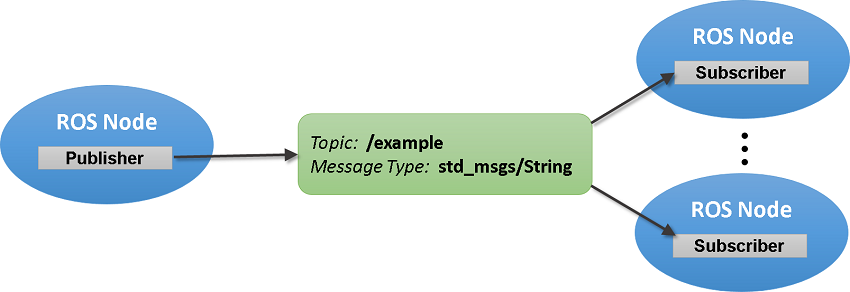

Besides how to publish and subscribe to topics in a ROS network, this example also shows how to:

- Wait until a new message is received

- Use callbacks to process new messages in the background

## 01 Runing the Network

Start the ROS master in MATLAB® using the [`rosinit`](docid:ros_ref.bupf5_j_1) command.

rosinit

Create a sample ROS network with several publishers and subscribers using the provided helper function `exampleHelperROSCreateSampleNetwork`.

ex_publish_net()

## 02 Studying the network

Use [rosnode](https://wiki.ros.org/ROS/Tutorials/UnderstandingNodes) list to see which nodes are available

rosnode list

/matlab_global_node_77404


Use [`rostopic`](docid:ros_ref.bupf5_j_14https://wiki.ros.org/ROS/Tutorials/UnderstandingTopics)` list` to see which topics are available.

rostopic list

/rosout
/scan  
/tf    
/twist 


Use `rostopic info` to check if any nodes are publishing to the `/scan` topic. The command below shows that `node_3` is publishing to it.

rostopic info /twist

Type: geometry_msgs/Twist
 
Publishers:
* /matlab_global_node_77404 (http://toro.bisonnet.lipscomb.edu:35473/)
 
Subscribers:


## 03 Listening to Published Data

Finally, let's see if any data is being streamed on that topic

rostopic echo /twist


  Linear     
    X :  0.03777789419264879
    Y :  -0.0463215528665995
    Z :  0.04609817895554251
  Angular    
    X :  0.001011308982104253
    Y :  0.04128396284488318
    Z :  0.007376013168785489
---

  Linear     
    X :  0.02225165721574109
    Y :  0.04036144614881386
    Z :  0.02856405917759074
  Angular    
    X :  0.008545971442799293
    Y :  0.02909821051197177
    Z :  0.02482910713914871
---

  Linear     
    X :  -0.01857591641406183
    Y :  0.0002156362990874516
    Z :  0.02416870538444386
  Angular    
    X :  0.003439548397213998
    Y :  0.01980470019897995
    Z :  0.01769015734164501
---

  Linear     
    X :  0.0266241106627749
    Y :  0.01346791959377689
    Z :  0.003900299311301792
  Angular    
    X :  0.01119966528778861
    Y :  0.03003036614980413
    Z :  0.01146553753248082
---

  Linear     
    X :  -0.0440980692958499
    Y :  -0.01574383657930376
    Z :  0.00286364236996548
  Angular    
    X :  -0.01648465757463387
    Y :  0.0075198

## **04 Geting Published Information via Subscribers**

Getting published information consists of two steps:

- Creating a ros subscriber

- Getting the data with that object

Furthermore, there are two methods to get the data:

- receive - single message

- subscription callback - continuous messaging

Let's explore this.

#### Creating a ROS subscriber object

Use [`rossubscriber`](docid:ros_ref.bupf5_j_9) to create a subscriber object to the `/scan` topic. 

- If the topic already exists in the ROS network (as is the case here), `rossubscriber` detects its message type automatically, so you do not need to specify it. 

- Use messages in struct format for better efficiency.

laser = rossubscriber("/scan","DataFormat","struct");
pause(2)    % To give a chance for network connections to happen

#### Receiving single messages

To receive a single published message you can use the [`receive`](docid:ros_ref.buqbyro)` function and pass the subscriber object to it.`

`Documentation:`

`tf = receive(message_name) extracts an input or local message from its receiving queue. If a valid message exists, receive returns true. If a valid message does not exist but there is a message in the queue, the chart removes the message from the queue and receive returns true. If a valid message does not exist and there are no messages in the queue, receive returns false.`

`Note:`

- It is possible to set a time-out in seconds in the 2nd argument. You can use the time-out in different ways, but it might be indicative of a problem. 

- The output `scandata` contains the received message data.

scandata = receive(laser,10)

scandata = struct with fields:
       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 struct]
          AngleMin: -0.5467
          AngleMax: 0.5467
    AngleIncrement: 0.0017
     TimeIncrement: 0
          ScanTime: 0.0330
          RangeMin: 0.4500
          RangeMax: 10
            Ranges: [640×1 single]
       Intensities: []


### **Visualization**

Some message types have visualizers associated with them. 

For the LaserScan message, `rosplot` plots the scan data. The `MaximumRange` name-value pair specifies the maximum plot range.

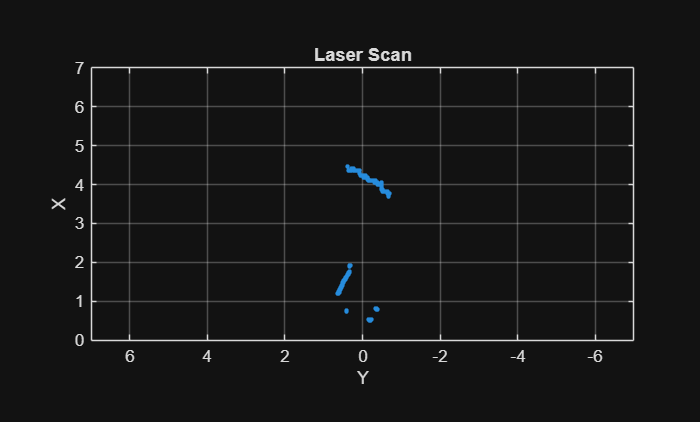

figure
rosPlot(scandata,"MaximumRange",7)

## 05 Subscribe Using Callback Functions

Instead of using [`receive`](docid:ros_ref.buqbyro) to get data, you can specify a function to be called anytime a new message is received. 

Receiving data may be happening in the order of 10s, 100s, or even 1000s of messages per second, but it may also start and stop. 

You do not want your code to stop and only move foward when data comes in. 

Callbacks, are a mechanism that allows other code to execute while the subscriber waits for new messages. 

Callbacks are the typical mechanism for subscribers:

Subscribe to the `/pose` topic, using the callback function `exampleHelperROSPoseCallback`.

robotTwist = rossubscriber("/twist", ...             % Topic from which you will get the data
                          @twist_callback, ...      % this callback, which always starts with @, will determine how data is handled
                          "DataFormat","struct");   % Tells matlab to handle incoming data as a structure which is more efficient

**robotTwist** may contain linear and angluar data inside. 

In the callback, you will be interested in copying the data from the topic onto a global variable in your code that you can then use elsewhere to achieve your goals. 

One way of sharing data between your main workspace and the callback function is to use *global variables*. 

Define two global variables `pos` and `orient`.

global lin_vel
global ang_vel

The global variables `lin_vel `and `ang_vel` are assigned in the `twist_callback` function when new message data is received on the `/twist` topic.

Wait for a few seconds to make sure that the subscriber can receive messages. 

The most current position and orientation data will always be stored in the `pos` and `orient` variables.

pause(0.5) 
lin_vel

lin_vel =     0.0110    0.0082   -0.0130


ang_vel

ang_vel =    -0.0423    0.0297   -0.0036


If you type in `pos` and `orient` a few times in the command line, you can see that the values are continuously updated.

Stop the pose subscriber by clearing the subscriber variable

clear robotTwist

*Note*: 

- There are other ways to extract information from callback functions besides using globals. 

- For example, you can pass a *handle object* as additional argument to the callback function. 

- See the [Callback Definition](docid:creating_plots.bt_h1z8) documentation for more information about defining callback functions.

## Another Publish-Subscribe Message

Create a publisher that sends ROS string messages to the `/chatter` topic (see [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)).

Note:

- If you create a publisher, you can choose the topic name. It is entirely up to you. 

- If you are connecting to an existing network, it is important you are familiar with the topic names. 

chatterpub = rospublisher("/chatter", ...           % We will publish to this topic 
                          "std_msgs/String", ...    % This is the type of the message. 
                          "DataFormat","struct")

chatterpub =   Publisher with properties:

         TopicName: '/chatter'
    NumSubscribers: 0
        IsLatching: 1
       MessageType: 'std_msgs/String'
        DataFormat: 'struct'


pause(2) % Wait to ensure publisher is registered

**Verify Newly Created Topic**

Use `rostopic list` to verify that the `/chatter` topic is available in the ROS network.

rostopic list

#### Message Types

Get familiar with the message types in ROS via the rosmsg show command:

rosmsg show std_msgs/String

Which outputs:

>> char Data

#### Populating the Message

To populate such message, we need to first create a message object of type std_msgs/String.

We can do that via the `rosmessage` command.

The rossmessage command can take two kinds of input:

- A string with the ros message type, i.e. 'std_msgs/String'

- A publisher object who has already been attributed a topic name and message type (as we did in L19-21):

chattermsg = rosmessage(chatterpub); 
% Alternatively you could also do: cattermsg = rosmessage('std_msgs/String')

After creating the message, you will want to fill it with relevant information before sending the data out to the robot network. 

Normally this would be goal information for the robot. Here we will do a simple string.

Note:

- chattermsg is a structure not a variable. 

- We want to set our goal string not to chattermsg itself, but to the relevant entry in the structure. In this case it is `chattermsg.Data:`

chattermsg.Data = 'hello world'

chattermsg = struct with fields:
    MessageType: 'std_msgs/String'
           Data: 'hello world'


#### Creating a Subscriber

Define a subscriber for the `/chatter` topic.  

`exampleHelperROSChatterCallback` is called when a new message is received and displays the string content in the message (do edit `exampleHelperROSChatterCallback) to see how it is called.`

chattersub = rossubscriber("/chatter", ...
                           @chatter_callback, ...
                           "DataFormat","struct")

chattersub =   Subscriber with properties:

                      TopicName: '/chatter'
                  LatestMessage: []
                    MessageType: 'std_msgs/String'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: @chatter_callback
                     DataFormat: 'struct'


#### Publish and Receive

In the next line, we will pubslih the `chattermsg` message to the `/chatter` topic via the `send` command. 

As soon as we do that, the message will be *caught* by the subscriber callback function we just created called: @exampleHelperROSChatterCallback.

As it catches that message, it will execute it's code (do 'edit exampleHelperROSChatterCallback') and display the string that has been published.

send(chatterpub,chattermsg)
pause(2)

ans = 'hello world'

#### Play with it

Change the  published msg value, publish it, and see the callback again:

chattermsg.Data = 'this is a new string'

chattermsg = struct with fields:
    MessageType: 'std_msgs/String'
           Data: 'this is a new string'


send(chatterpub,chattermsg)

## Shut Down ROS Network

Remove the sample nodes, publishers, and subscribers from the ROS network one by one via the `clear('object')` command as seen in (edit exampleHelperROSShutDownSampleNetwork):

Clear the global variables `pos` and `orient.`

exampleHelperROSShutDownSampleNetwork
clear global lin_vel ang_Vel

Shut down the ROS master and delete the global node.

rosshutdown